First we will check whether this data is continous. 

%h5disp('test_E-P2/trajectory0/blocks_0-99.h5');
sample_pos=[];
time_list=[];
for i=0:9
    for j=i*100:i*100+99
        F=['test_E-P2/trajectory0/blocks_',num2str(i*100),'-',num2str(i*100+99),'.h5'];
        pos=h5read(F,['////',num2str(j),'/pos']);
        sample_pos=[sample_pos,pos(:,250)];
        time=h5readatt(F,['////',num2str(j)],'time');
        time_list=[time_list,time];
    end
end

Plotting

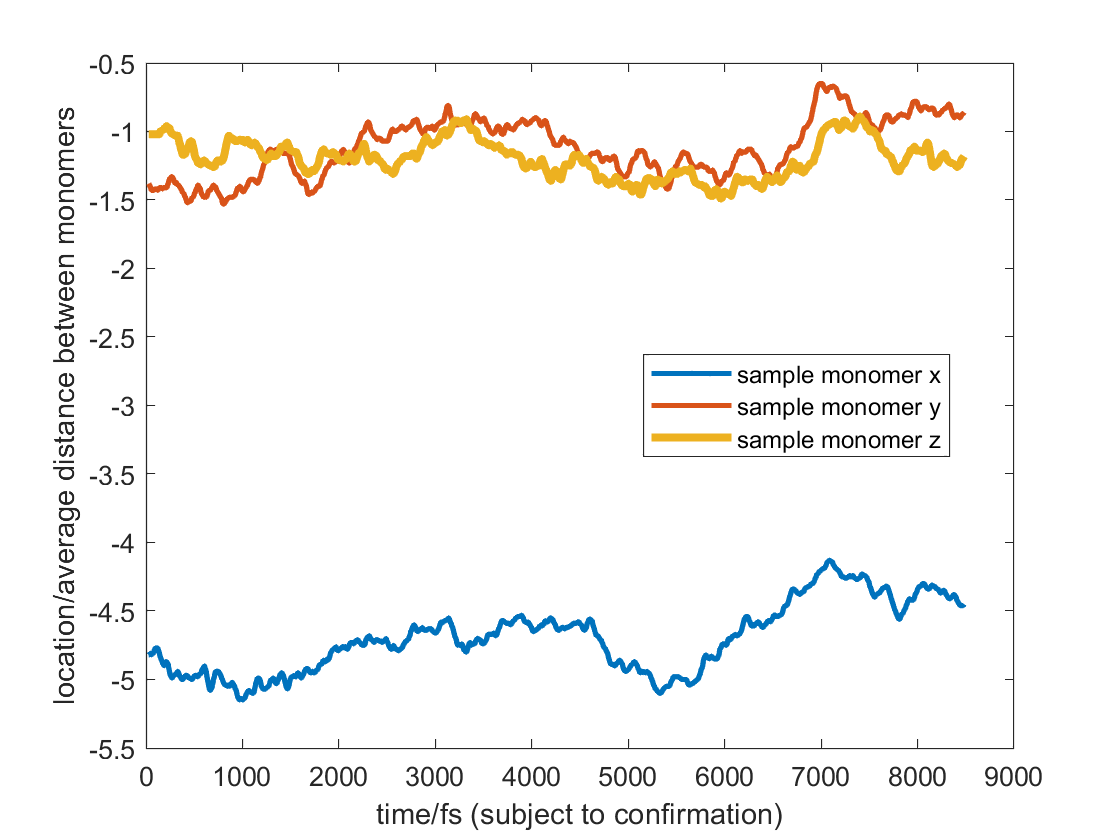

figure
plot(time_list(1,:),sample_pos(1,:),"LineWidth",2,"DisplayName",'sample monomer x')
hold on
plot(time_list(1,:),sample_pos(2,:),"LineWidth",2,"DisplayName",'sample monomer y')
plot(time_list(1,:),sample_pos(3,:),"LineWidth",3,"DisplayName",'sample monomer z')
xlabel('time/fs (subject to confirmation)')
ylabel('location/average distance between monomers')
legend("Location","best")